clc; clear; close all;

% IMPORT URDF

robot = importrobot("C:/Users/aryan/OneDrive/Desktop/2dof/Assem1/urdf/Assem1.urdf");  % paste the urdf location
robot.DataFormat = "column";
robot.Gravity = [0 0 -9.81];

showdetails(robot)

--------------------
Robot: (4 bodies)

 Idx        Body Name           Joint Name           Joint Type        Parent Name(Idx)   Children Name(s)
 ---        ---------           ----------           ----------        ----------------   ----------------
   1        base_link          world_joint                fixed                world(0)   link1(2)  
   2            link1              joint_1             revolute            base_link(1)   link2(3)  
   3            link2              joint_2             revolute                link1(2)   payload(4)  
   4          payload        payload_joint                fixed                link2(3)   
--------------------



% SIMULATION PARAMETERS

dt = 0.01;
T  = 20;
t  = 0:dt:T;
N  = length(t);
L1 = 0.4;   % meters
L2 = 0.35;

m1 = 1.5;   % realistic aluminum link
m2 = 1.2;

I1 = (1/12)*m1*L1^2;
I2 = (1/12)*m2*L2^2;

n = numel(homeConfiguration(robot));

q  = zeros(n,1);
qd = zeros(n,1);

Kp = diag([80 60]);
Kd = diag([15 10]);
Ki = diag([3 2]);

q_int = zeros(n,1);
q_log = zeros(n,N);

q_des_log = zeros(n,N);
tau_log   = zeros(n,N);
dist_log = zeros(n,N);
ee_log     = zeros(3,N);
ee_des_log = zeros(3,N);

% DYNAMIC SIMULATION

for i = 1:N

    time = t(i);

    if time <= 7
        q_des = [ (pi/4)*sin(0.3*time);
                  (pi/6)*sin(0.3*time) ];
        qd_des = [ (pi/4)*0.3*cos(0.3*time);
                   (pi/6)*0.3*cos(0.3*time) ];
        qdd_des = [ -(pi/4)*(0.3^2)*sin(0.3*time);
                    -(pi/6)*(0.3^2)*sin(0.3*time) ];

    elseif time <= 14
        tau_time = time - 7;
        q_des = [ (pi/3)*sin(0.4*tau_time);
                  (pi/4)*cos(0.4*tau_time) ];
        qd_des = [ (pi/3)*0.4*cos(0.4*tau_time);
                  -(pi/4)*0.4*sin(0.4*tau_time) ];
        qdd_des = [ -(pi/3)*(0.4^2)*sin(0.4*tau_time);
                    -(pi/4)*(0.4^2)*cos(0.4*tau_time) ];

    else
        tau_time = time - 14;
        q_des = [ (pi/4)*(1 - tau_time/6);
                  (pi/6)*(1 - tau_time/6) ];
        qd_des = [ -(pi/4)/6;
                   -(pi/6)/6 ];
        qdd_des = [0;0];
    end

    M = massMatrix(robot,q);
    G = gravityTorque(robot,q);
    C = velocityProduct(robot,q,qd);

    

    e     = q_des - q;
    e_dot = qd_des - qd;
    q_int = q_int + e*dt;

    v_control = qdd_des + Kd*e_dot + Kp*e + Ki*q_int;
    tau = M*v_control + C + G;

    % External disturbance
     disturbance = [0.5*sin(0.5*time);
               0.3*cos(0.5*time)];

     tau_total = tau + disturbance;

     qdd = M \ (tau_total - C - G);

     dist_log(:,i) = disturbance;

    qd = qd + qdd*dt;
    q  = q  + qd*dt;

    q_log(:,i) = q;
    % Cartesian Tracking 
    T_current = getTransform(robot,q,"payload");
    ee_log(:,i) = T_current(1:3,4);

    T_des = getTransform(robot,q_des,"payload");
    ee_des_log(:,i) = T_des(1:3,4);
    q_des_log(:,i) = q_des;
    tau_log(:,i)   = tau;
end
error1 = q_des_log(1,:) - q_log(1,:);
error2 = q_des_log(2,:) - q_log(2,:);

rmse1 = sqrt(mean(error1.^2));
rmse2 = sqrt(mean(error2.^2));

fprintf('RMSE Joint 1: %.6f rad\n', rmse1);

RMSE Joint 1: 0.059429 rad


fprintf('RMSE Joint 2: %.6f rad\n', rmse2);

RMSE Joint 2: 0.119894 rad


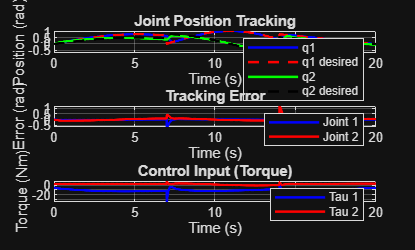


%        PLOTS

figure;

% Joint Position Tracking

subplot(3,1,1)
plot(t, q_log(1,:), 'b', 'LineWidth',1.5); hold on;
plot(t, q_des_log(1,:), 'r--', 'LineWidth',1.5);
plot(t, q_log(2,:), 'g', 'LineWidth',1.5);
plot(t, q_des_log(2,:), 'k--', 'LineWidth',1.5);
grid on
xlabel('Time (s)')
ylabel('Position (rad)')
title('Joint Position Tracking')
legend('q1','q1 desired','q2','q2 desired')

% Tracking Error

subplot(3,1,2)
plot(t, q_des_log(1,:) - q_log(1,:), 'b', 'LineWidth',1.5); hold on;
plot(t, q_des_log(2,:) - q_log(2,:), 'r', 'LineWidth',1.5);
grid on
xlabel('Time (s)')
ylabel('Error (rad)')
title('Tracking Error')
legend('Joint 1','Joint 2')

% Control Torque
subplot(3,1,3)
plot(t, tau_log(1,:), 'b', 'LineWidth',1.5); hold on;
plot(t, tau_log(2,:), 'r', 'LineWidth',1.5);
grid on
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Control Input (Torque)')
legend('Tau 1','Tau 2')

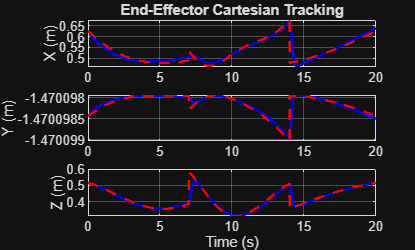

% Cartesian Tracking Plot
figure;

subplot(3,1,1)
plot(t, ee_log(1,:), 'b', t, ee_des_log(1,:), 'r--','LineWidth',1.5)
ylabel('X (m)')
title('End-Effector Cartesian Tracking')
grid on

subplot(3,1,2)
plot(t, ee_log(2,:), 'b', t, ee_des_log(2,:), 'r--','LineWidth',1.5)
ylabel('Y (m)')
grid on

subplot(3,1,3)
plot(t, ee_log(3,:), 'b', t, ee_des_log(3,:), 'r--','LineWidth',1.5)
ylabel('Z (m)')
xlabel('Time (s)')
grid on

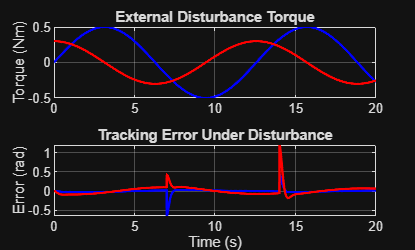


figure;

subplot(2,1,1)
plot(t, dist_log(1,:), 'b', t, dist_log(2,:), 'r','LineWidth',1.5)
title('External Disturbance Torque')
ylabel('Torque (Nm)')
grid on

subplot(2,1,2)
plot(t, q_des_log(1,:) - q_log(1,:), 'b', ...
     t, q_des_log(2,:) - q_log(2,:), 'r','LineWidth',1.5)
title('Tracking Error Under Disturbance')
xlabel('Time (s)')
ylabel('Error (rad)')
grid on

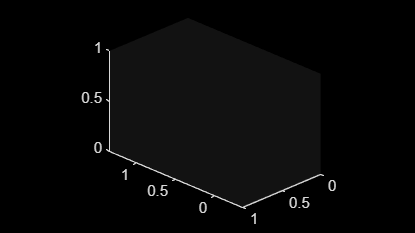

% STABLE VIDEO RECORDING 

videoFile = "C:/Users/aryan/OneDrive/Desktop/2dof/3D_robot_arm.mp4"; % paste the location where want to save the video

videoObj = VideoWriter(videoFile,'MPEG-4');
videoObj.FrameRate = 30;
open(videoObj);

%  CLASSIC FIGURE 
fig = figure('Color','k');
set(fig,'Position',[100 100 1280 720]);
set(fig,'Renderer','opengl');

ax = axes('Parent',fig);
axis(ax,'equal')
view(ax,-135,25)
camlight(ax,'headlight')

lighting(ax,'gouraud')

drawnow;



for k = 1:N

    cla(ax);   % Clear axis ONLY

    show(robot,q_log(:,k), ...
        'Parent',ax, ...
        'PreservePlot',false);

    axis(ax,'equal')
    zlim(ax,[0 1.5])
    view(ax,-135,25)

    title(ax,sprintf('Time = %.2f sec', t(k)),'Color','w');

    drawnow;

    frame = getframe(fig);

    img = imresize(frame.cdata,[720 1280]);

    writeVideo(videoObj, img);

end

Error using getframe (line 56)
A valid figure or axes handle must be specified


close(videoObj);

disp("Video saved successfully.");
disp(videoFile);

